### Description: Code to calculate  FFT  and HHT of a stationary signal with Beating Phenomenon

### Author: Vishu Sharma

### Last Modified: 07.12.2021

clear all, clc

Fs = .125; % Sampling frequency
T = 1/Fs; % Sampling period
L = 512; % length of signal
t = (0: L-1)*T;
r=2*pi;

## Signal and Noise

A = 1*sin(1/30 *r*t);
B = 1.2*sin(1/33*r*t);
N = 0*rand(size(t));

x = A + B+ N;

## Signal in time domain

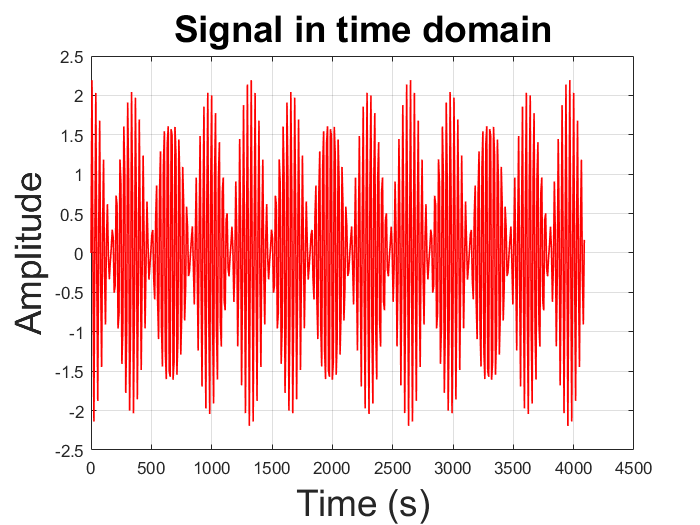

plot(t,x, 'r','LineWidth',1)
grid on
title('Signal in time domain', 'FontSize', 22)
xlabel('Time (s)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

## Fourier Spectral Analysis

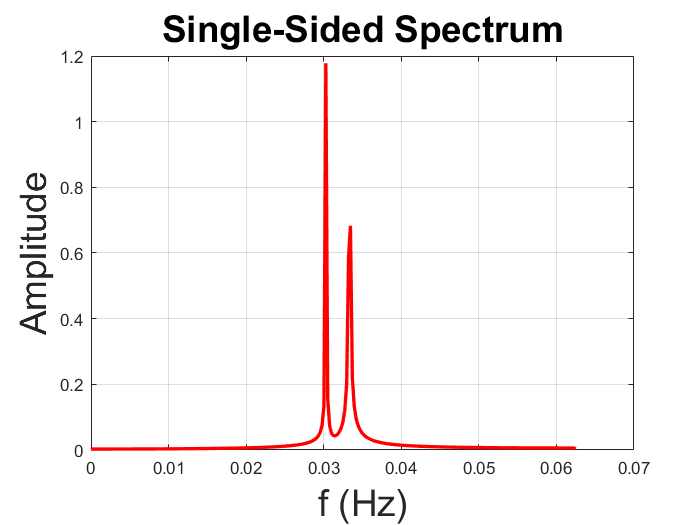

n = 2^nextpow2(L);         % num of points for FFT

Y = fft(x);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1,'r','LineWidth',2) 

title('Single-Sided Spectrum','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude', 'FontSize', 22)

grid on

## Spectogram

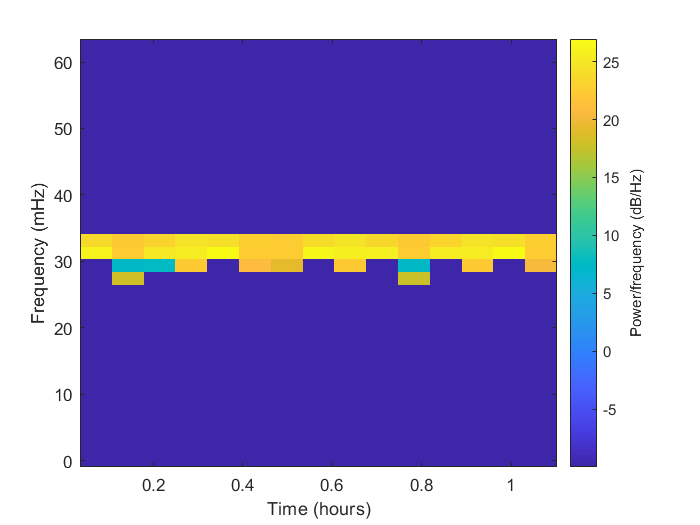

 s = spectrogram(x);
 spectrogram(x, window(@hanning,64), 32, 64, Fs,'yaxis', 'reassign','MinThreshold', -10)

## HHT

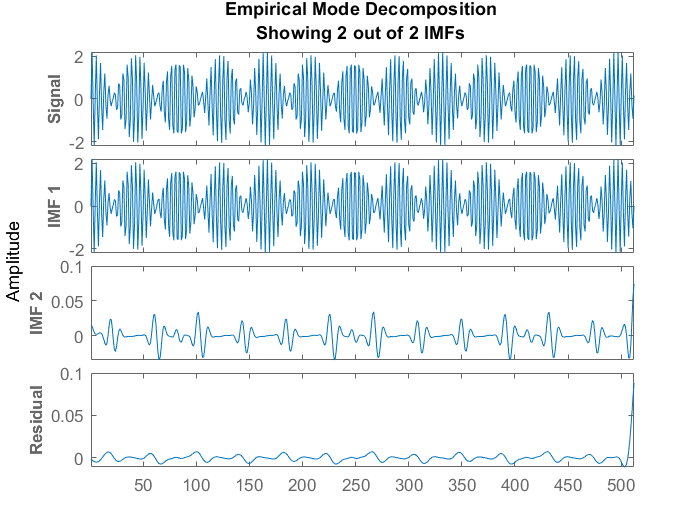

%hht(x)


emd(x,'MaxNumIMF',5)

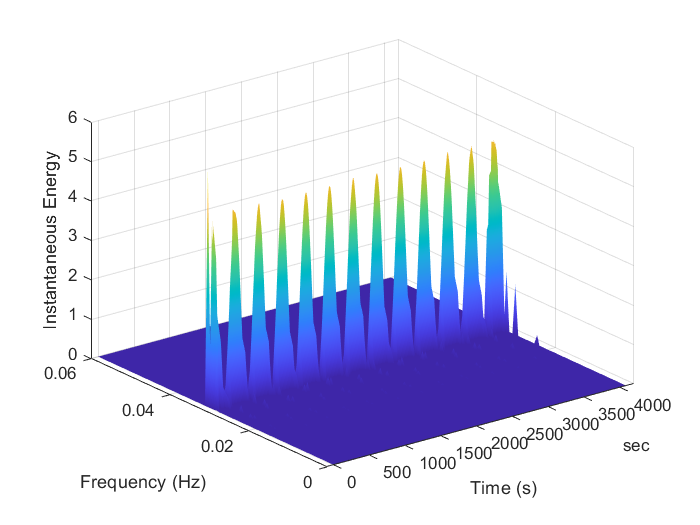

imf = emd(x);
[hs,F,t] = hht(imf,Fs,'FrequencyLimits',[0 .06]);

mesh(seconds(t),F,hs,'EdgeColor','none','FaceColor','interp')
xlabel('Time (s)')
ylabel('Frequency (Hz)')
zlabel('Instantaneous Energy')